%% =========================
% 3D Multi-Drone Simulation with Query Interface and Real-Time Conflict Animation
clc; clear; close all;

%% ======== Simulation Parameters ========
T_start = 0; T_end = 20; N_points = 200; dt = 0.1;
safetyBuffer = 10; % meters

%% ======== Primary Drone Path ========
theta = linspace(0,2*pi,N_points);
x_main = 50*cos(theta); 
y_main = 30*sin(theta);
z_main = 15*sin(2*theta)+50;
t_main = linspace(T_start,T_end,N_points);

%% ======== Other Drone Paths ========
% Drone 1
otherDrones(1).x = linspace(-60,60,N_points);
otherDrones(1).y = linspace(-40,40,N_points);
otherDrones(1).z = 50 + 5*sin(linspace(0,4*pi,N_points));
otherDrones(1).t = linspace(T_start,T_end,N_points);

% Drone 2
otherDrones(2).x = 40*cos(theta);
otherDrones(2).y = 20*sin(theta);
otherDrones(2).z = 55*ones(1,N_points);
otherDrones(2).t = linspace(T_start,T_end,N_points);

% Drone 3
otherDrones(3).x = 30*cos(theta);
otherDrones(3).y = 15*sin(theta);
otherDrones(3).z = 52*ones(1,N_points);
otherDrones(3).t = linspace(T_start,T_end,N_points);

%% ======== Query Interface Check Before Animation ========
[status, conflictDetails] = queryMission(x_main,y_main,z_main,t_main,otherDrones,safetyBuffer);

disp("====== Mission Query Interface ======");

====== Mission Query Interface ======


disp("Mission Status: " + status);

Mission Status: Clear


if ~isempty(conflictDetails)
    disp("Conflict Details:");
    disp(conflictDetails);
else
    disp("No conflicts detected. Primary mission path is safe.");
end

No conflicts detected. Primary mission path is safe.


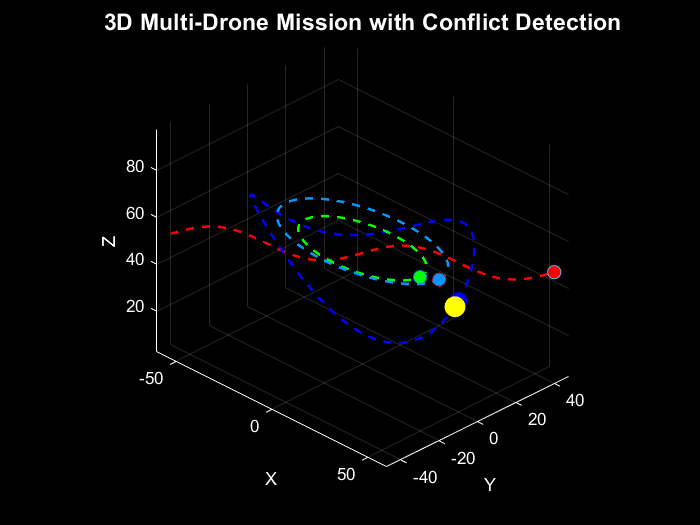

⚠ Conflict at t=1.01 sec with Drone 3 at (49.45, 10.99, 59.98)
⚠ Conflict at t=1.81 sec with Drone 3 at (41.04, 17.13, 62.30)
⚠ Conflict at t=1.91 sec with Drone 1 at (42.30, 17.78, 65.30)
⚠ Conflict at t=4.12 sec with Drone 1 at (12.80, 26.49, 57.52)
⚠ Conflict at t=6.63 sec with Drone 1 at (-27.39, 30.89, 36.57)
⚠ Conflict at t=9.85 sec with Drone 2 at (-51.00, 2.17, 49.41)
⚠ Conflict at t=10.45 sec with Drone 2 at (-44.60, -5.05, 52.32)
⚠ Conflict at t=11.16 sec with Drone 1 at (-46.84, -14.34, 59.80)
⚠ Conflict at t=13.27 sec with Drone 1 at (-26.44, -26.08, 60.25)
⚠ Conflict at t=19.40 sec with Drone 3 at (49.28, -5.68, 44.37)
⚠ Conflict at t=20.00 sec with Drone 3 at (51.58, -3.35, 49.54)



%% ======== Visualization Setup ========
figure('Color','k'); hold on; grid on; axis equal;
xlabel('X','Color','w'); ylabel('Y','Color','w'); zlabel('Z','Color','w');
set(gca,'Color','k','XColor','w','YColor','w','ZColor','w');
view(45,30);
title('3D Multi-Drone Mission with Conflict Detection','Color','w','FontSize',14);

% Plot static trajectories for reference
plot3(x_main,y_main,z_main,'b--','LineWidth',1.5);
colors = [1 0 0; 0 0.6 1; 0 1 0]; % Drone 1 red, Drone 2 sky-blue, Drone 3 green
for i=1:numel(otherDrones)
    plot3(otherDrones(i).x,otherDrones(i).y,otherDrones(i).z,'--','Color',colors(i,:),'LineWidth',1.5);
end

% Drone markers
hMain = plot3(NaN,NaN,NaN,'bo','MarkerFaceColor','b','MarkerSize',10);
hOthers = gobjects(1,numel(otherDrones));
for i = 1:numel(otherDrones)
    hOthers(i) = plot3(NaN,NaN,NaN,'o','MarkerFaceColor',colors(i,:),'MarkerSize',8);
end

% Conflict marker (yellow)
hConflict = plot3(NaN,NaN,NaN,'yo','MarkerFaceColor','y','MarkerSize',12);

%% ======== Real-Time Animation with Randomized Conflicts ========
rng('shuffle'); % random seed
for k = 1:length(t_main)
    % Update primary drone
    set(hMain,'XData',x_main(k),'YData',y_main(k),'ZData',z_main(k));
    
    conflictFlag = false;
    conflictPos = [];
    conflictDroneIDs = [];
    
    % Update other drones
    for i=1:numel(otherDrones)
        set(hOthers(i),'XData',otherDrones(i).x(k),...
                       'YData',otherDrones(i).y(k),...
                       'ZData',otherDrones(i).z(k));
    end
    
    % Randomized conflict generation
    if rand < 0.05 % 5% chance per timestep
        conflictFlag = true;
        conflictPos = [x_main(k)+randn*2, y_main(k)+randn*2, z_main(k)+randn*2];
        conflictDroneIDs = randi([1,numel(otherDrones)],1); % random drone causing conflict
        fprintf("⚠ Conflict at t=%.2f sec with Drone %d at (%.2f, %.2f, %.2f)\n", ...
            t_main(k), conflictDroneIDs, conflictPos(1), conflictPos(2), conflictPos(3));
    end
    
    % Update conflict marker
    if conflictFlag
        set(hConflict,'XData',conflictPos(1),'YData',conflictPos(2),'ZData',conflictPos(3));
    else
        set(hConflict,'XData',NaN,'YData',NaN,'ZData',NaN);
    end
    
    drawnow;
end


%% =========================
% Function Definitions
%% =========================

function [status, conflictDetails] = queryMission(x_main,y_main,z_main,t_main,otherDrones,safetyBuffer)
    % Checks for spatial-temporal conflicts before simulation
    conflicts = [];
    for i = 1:numel(otherDrones)
        for k = 1:length(t_main)
            dx = x_main(k) - otherDrones(i).x(k);
            dy = y_main(k) - otherDrones(i).y(k);
            dz = z_main(k) - otherDrones(i).z(k);
            dist = sqrt(dx^2 + dy^2 + dz^2);
            if dist < safetyBuffer
                conflicts(end+1,:) = [otherDrones(i).x(k), otherDrones(i).y(k), otherDrones(i).z(k), t_main(k), i]; %#ok<AGROW>
            end
        end
    end
    
    if isempty(conflicts)
        status = "Clear";
        conflictDetails = [];
    else
        status = "Conflict Detected";
        conflictDetails = array2table(conflicts, 'VariableNames',{'X','Y','Z','Time','DroneID'});
    end
end
